load('C:\Users\mrsco\Box\DataAndAnalysis\labData\OKR\batch\cellList_OKR2P.mat')

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ID1005'}; %child field name should be one of these. Priority is in given order
priorityOrder_2b = {'_ID1007'};
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ID1005'};
mustHave_2b = {'Extracellular', '_ID1007'};
cantHave_1 = [];
cantHave_2 = {}; %avoid anything with these tags
rigMandates = []; %no rig mandates

upPDs = [];
downPDs = [];
upDSIs = [];
downDSIs = [];
upTCAreas = [];
downTCAreas = [];
upNormedAreas = [];
downNormedAreas = [];

upCoords = zeros(0, 2);
downCoords = zeros(0, 2);

upDSIs_HighLow = zeros(0, 2);
downDSIs_HighLow = zeros(0, 2);
upNormedAreas_HighLow = zeros(0, 2);
downNormedAreas_HighLow = zeros(0, 2);
upTCAreas_HighLow = zeros(0, 2);
downTCAreas_HighLow = zeros(0, 2);

hasLowC = [];
lowC_CellTypes = [];
for i = 1:size(cellList, 1)
    struct_i = cellList{i, 2};
    %ask whether the current cell has the requested analysis
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_lowC, pass_lowC] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2b, mustHave_2b, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    if contains(struct_i.cellID, 'SHOKR119L')
        continue
    end
    disp(struct_i.cellID)
    pd = mod(loc.Analysis_Results.PreferredDirection, 360);
    dsi = loc.Analysis_Results.DSI;
    tcArea = calculateSpikeTCArea(loc);
    spikeMetrics = SpikeMetricHelper(loc);
    normedArea = spikeMetrics.NormalizedTuningCurveArea;
    [coordX, coordY] = pol2cart(struct_i.coordinates.polar(1),struct_i.coordinates.polar(2));
    
    tags = struct_i.Tags;
    if ismember('UP Cell', tags)
        upPDs(end+1) = pd;
        upDSIs(end + 1) = dsi;
        upTCAreas(end + 1) = tcArea;
        upCoords(end+1, :) = [-coordX, coordY];
        upNormedAreas(end+1) = normedArea;
    elseif ismember('DOWN Cell', tags)
        downPDs(end+1) = pd;
        downDSIs(end + 1) = dsi;
        downTCAreas(end + 1) = tcArea;
        downCoords(end+1, :) = [-coordX, coordY];
        downNormedAreas(end + 1) = normedArea;
    end
    
    if pass_lowC
        continue
    end
    
    dsi_lowC = loc_lowC.Analysis_Results.DSI;
    
    tcArea_lowC = calculateSpikeTCArea(loc_lowC);
    spikeMetrics_lowC = SpikeMetricHelper(loc_lowC);
    normedArea_lowC = spikeMetrics_lowC.NormalizedTuningCurveArea;
    
    tags = struct_i.Tags;
    if ismember('UP Cell', tags)
        upDSIs_HighLow(end + 1, :) = [dsi;dsi_lowC];
        upTCAreas_HighLow(end+ 1, :) = [tcArea; tcArea_lowC];
        upNormedAreas_HighLow(end + 1, :) = [normedArea, normedArea_lowC];
    elseif ismember('DOWN Cell', tags)
        downDSIs_HighLow(end + 1, :) = [dsi;dsi_lowC];
        downTCAreas_HighLow(end + 1, :) = [tcArea; tcArea_lowC];
        downNormedAreas_HighLow(end + 1, :) = [normedArea, normedArea_lowC];
    end
end

SHOKR115Lc3
SHOKR115Lc4
SHOKR115Lc5
SHOKR115Lc6
SHOKR115Lc1
SHOKR115Lc2
SHOKR115Lc7
SHOKR115Lc8
SHOKR115Lc9
SHOKR115Lc10
SHOKR115Lc11
SHOKR115Lc12
SHOKR115Lc13
SHOKR117Lc1
SHOKR117Lc2
SHOKR117Lc5
SHOKR117Lc6
SHOKR117Lc7
SHOKR117Lc8
SHOKR117Lc9
SHOKR117Lc10
SHOKR117Lc11
SHOKR117Lc12
SHOKR117Lc14
SHOKR116Lc1
SHOKR116Lc2
SHOKR116Lc3
SHOKR116Lc4
SHOKR116Lc5
SHOKR116Lc6
SHOKR116Lc7
SHOKR116Lc8
SHOKR116Lc9
SHOKR116Lc10
SHOKR116Lc11
SHOKR116Lc12
SHOKR116Lc14
SHOKR116Lc15
SHOKR116Lc16
SHOKR116Lc17
SHOKR118Lc1
SHOKR118Lc2
SHOKR118Lc3
SHOKR118Lc4
SHOKR118Lc5
SHOKR118Lc6
SHOKR118Lc7
SHOKR118Lc8
SHOKR118Lc9
SHOKR118Lc10
SHOKR118Lc11
SHOKR118Lc12
SHOKR121Lc1
SHOKR121Lc2
SHOKR121Lc4
SHOKR121Lc5
SHOKR121Lc6
SHOKR121Lc7
SHOKR121Lc8
SHOKR121Lc9
SHOKR121Lc10


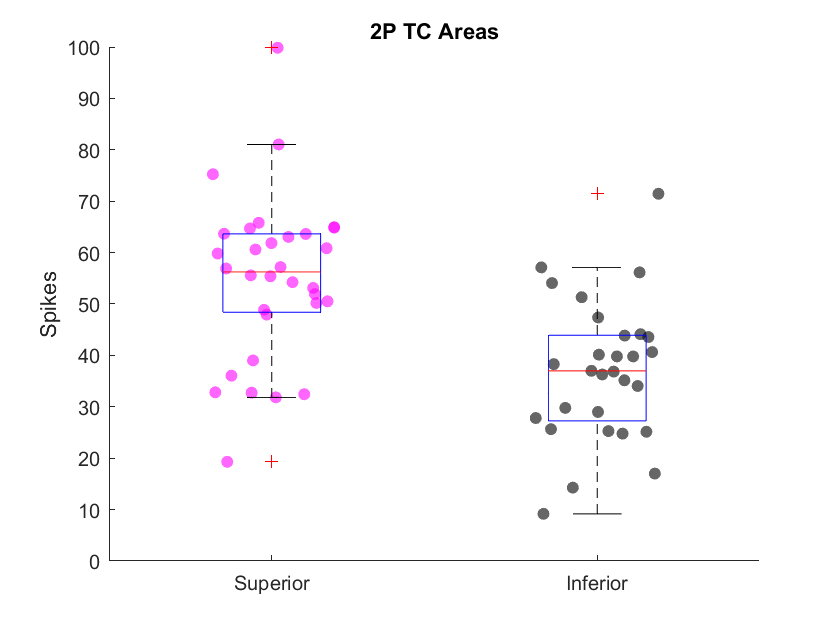

allVals = [downTCAreas, upTCAreas];
boxPlotGroups = zeros(1, numel(allVals));
boxPlotGroups(numel(downTCAreas)+1:end) = 1;

figure
title('2P TC Areas')
hold on
scatter(zeros(1, numel(downTCAreas))+1, downTCAreas, 'm', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
scatter(zeros(1, numel(upTCAreas))+2, upTCAreas, 'k', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
boxplot(allVals, boxPlotGroups)
ylabel('Spikes')
ylim([0 100])
box off
xticklabels({'Superior', 'Inferior'})

p = ranksum(downTCAreas, upTCAreas)

p = 5.1005e-05

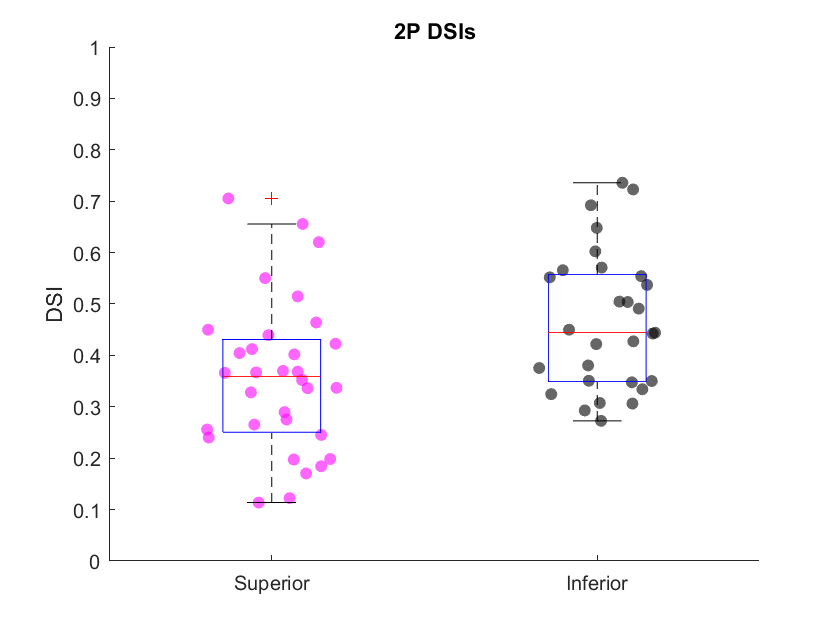

allVals = [downDSIs, upDSIs];
boxPlotGroups = zeros(1, numel(allVals));
boxPlotGroups(numel(downDSIs)+1:end) = 1;

figure
title('2P DSIs')
hold on
scatter(zeros(1, numel(downDSIs))+1, downDSIs, 'm', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
scatter(zeros(1, numel(upDSIs))+2, upDSIs, 'k', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
boxplot(allVals, boxPlotGroups)
ylabel('DSI')
ylim([0 1])
box off
xticklabels({'Superior', 'Inferior'})

p = ranksum(upDSIs, downDSIs)

p = 0.0052

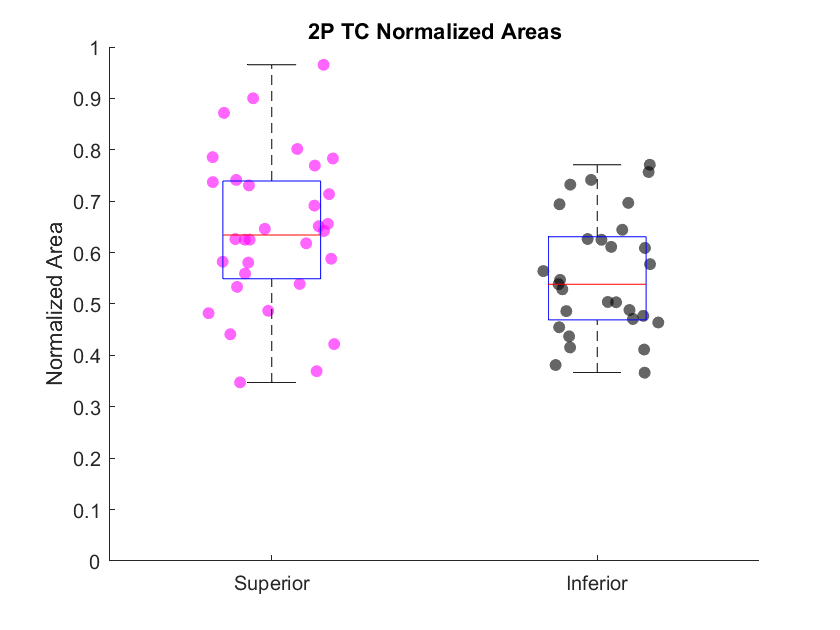


allVals = [downNormedAreas, upNormedAreas];
boxPlotGroups = zeros(1, numel(allVals));
boxPlotGroups(numel(downNormedAreas)+1:end) = 1;

figure
title('2P TC Normalized Areas')
hold on
scatter(zeros(1, numel(downNormedAreas))+1, downNormedAreas, 'm', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
scatter(zeros(1, numel(upNormedAreas))+2, upNormedAreas, 'k', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
boxplot(allVals, boxPlotGroups)
ylabel('Normalized Area')
ylim([0 1])
box off
xticklabels({'Superior', 'Inferior'})

p = ranksum(upNormedAreas, downNormedAreas)

p = 0.0175

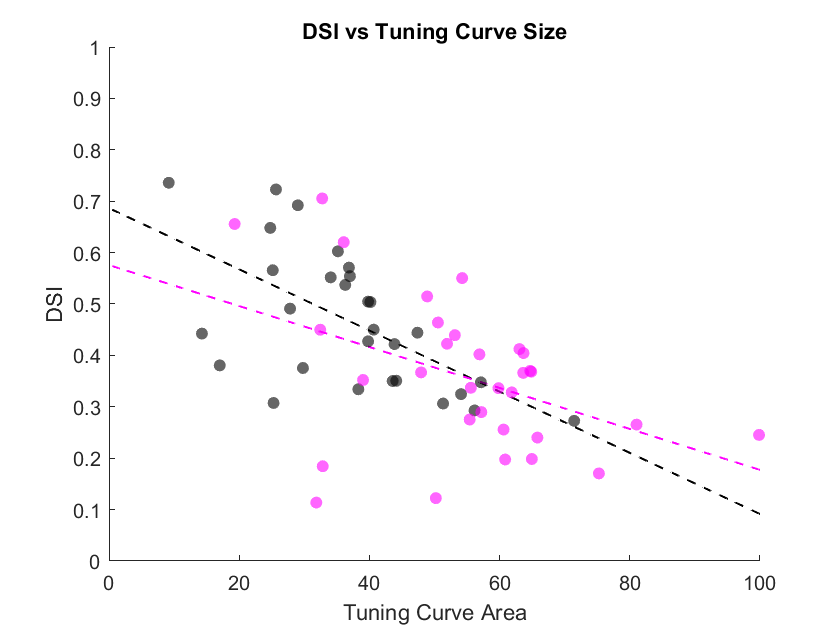

mdlUpAreas = fitlm(upTCAreas, upDSIs);
mdlDownAreas = fitlm(downTCAreas, downDSIs);

fitQueries = [0.5:0.1:100];

upMdlPredictions = feval(mdlUpAreas, fitQueries);
downMdlPredictions = feval(mdlDownAreas, fitQueries);


figure
title('DSI vs Tuning Curve Size')
hold on
plot(fitQueries, upMdlPredictions, '--k', 'LineWidth', 1)
plot(fitQueries, downMdlPredictions, '--m', 'LineWidth', 1)
scatter(upTCAreas, upDSIs, 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downTCAreas, downDSIs, 'filled', 'm', 'MarkerFaceAlpha', 0.6)
ylim([0 1])
xlabel('Tuning Curve Area')
ylabel('DSI')

[r, p] = corr(upTCAreas', upDSIs', 'type','Spearman')

r = -0.6203

p = 3.3151e-04

[r, p] = corr(downTCAreas', downDSIs', 'type','Spearman')

r = -0.3911

p = 0.0276

## Low Contrast

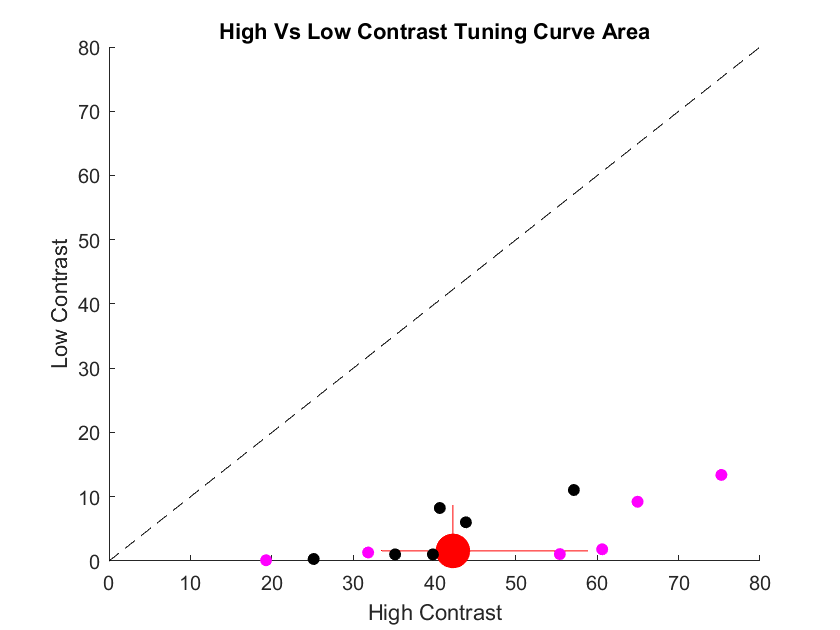

overallMedianX = median([upTCAreas_HighLow(:, 1); downTCAreas_HighLow(:, 1)]);
overallMedianY = median([upTCAreas_HighLow(:, 2); downTCAreas_HighLow(:, 2)]);
[~, ~, xOverallER1, xOverallER2] = medianCI95Bootstrap([upTCAreas_HighLow(:, 1); downTCAreas_HighLow(:, 1)], 10000);
[~, ~, yOverallER1, yOverallER2] = medianCI95Bootstrap([upTCAreas_HighLow(:, 2); downTCAreas_HighLow(:, 2)], 10000);

figure
title ('High Vs Low Contrast Tuning Curve Area')
hold on
scatter(overallMedianX, overallMedianY, 300, 'filled', 'r')
plot([-xOverallER1, xOverallER2]+overallMedianX, [overallMedianY, overallMedianY], 'r')
plot([overallMedianX, overallMedianX], [-yOverallER1, yOverallER2] + overallMedianY, 'r')
scatter(upTCAreas_HighLow(:, 1), upTCAreas_HighLow(:, 2), 'k', 'filled')
scatter(downTCAreas_HighLow(:, 1), downTCAreas_HighLow(:, 2), 'm', 'filled')
plot([0 80], [0 80], '--k')
xlim([0 80])
ylim([0 80])
xlabel('High Contrast')
ylabel('Low Contrast')

p = signrank([upTCAreas_HighLow(:, 1); downTCAreas_HighLow(:, 1)], [upTCAreas_HighLow(:, 2); downTCAreas_HighLow(:, 2)])

p = 4.8828e-04

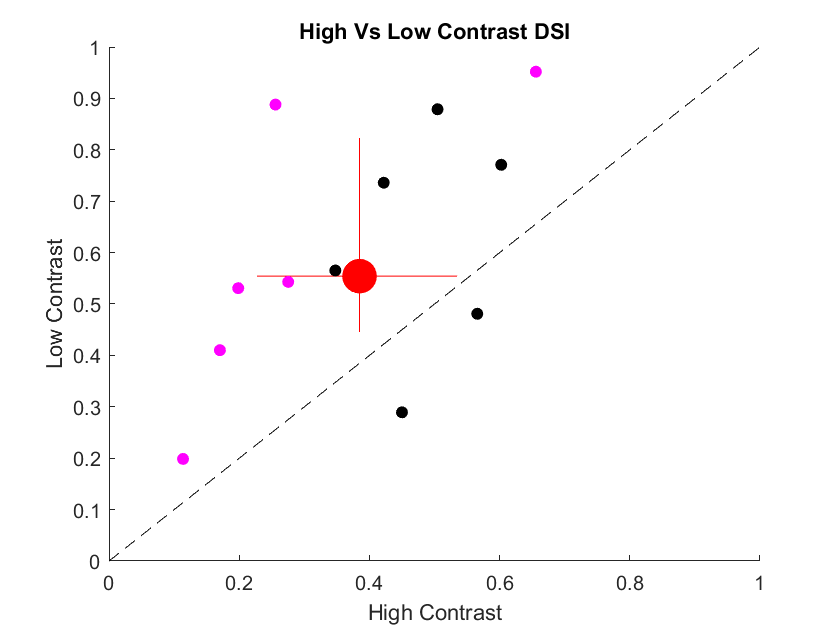


overallMedianX = median([upDSIs_HighLow(:, 1); downDSIs_HighLow(:, 1)]);
overallMedianY = median([upDSIs_HighLow(:, 2); downDSIs_HighLow(:, 2)]);
[~, ~, xOverallER1, xOverallER2] = medianCI95Bootstrap([upDSIs_HighLow(:, 1); downDSIs_HighLow(:, 1)], 10000);
[~, ~, yOverallER1, yOverallER2] = medianCI95Bootstrap([upDSIs_HighLow(:, 2); downDSIs_HighLow(:, 2)], 10000);

figure
title ('High Vs Low Contrast DSI')
hold on
scatter(overallMedianX, overallMedianY, 300, 'filled', 'r')
plot([-xOverallER1, xOverallER2]+overallMedianX, [overallMedianY, overallMedianY], 'r')
plot([overallMedianX, overallMedianX], [-yOverallER1, yOverallER2] + overallMedianY, 'r')
scatter(upDSIs_HighLow(:, 1), upDSIs_HighLow(:, 2), 'k', 'filled')
scatter(downDSIs_HighLow(:, 1), downDSIs_HighLow(:, 2), 'm', 'filled')
plot([0 1], [0 1], '--k')
xlabel('High Contrast')
ylabel('Low Contrast')

p = signrank([upDSIs_HighLow(:, 1); downDSIs_HighLow(:, 1)], [upDSIs_HighLow(:, 2); downDSIs_HighLow(:, 2)])

p = 0.0034

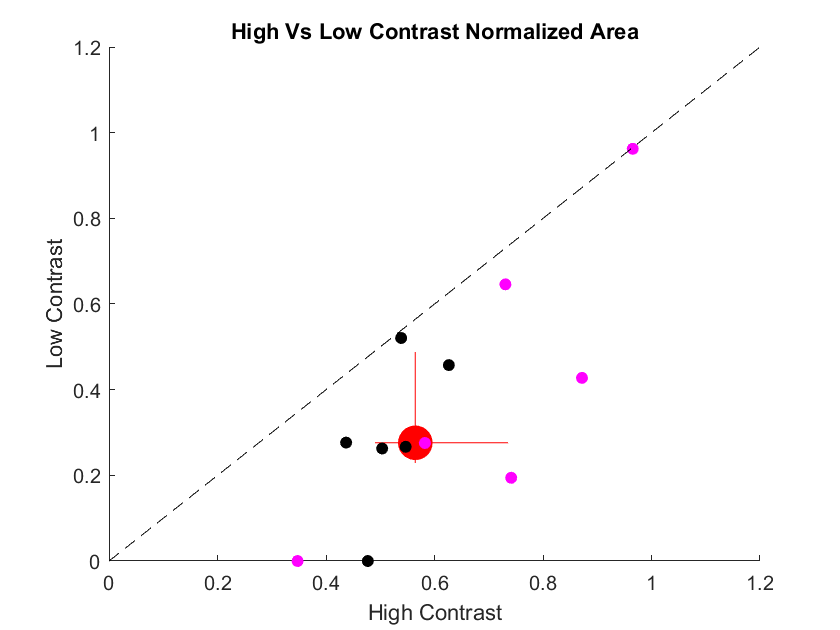

overallMedianX = median([upNormedAreas_HighLow(:, 1); downNormedAreas_HighLow(:, 1)]);
overallMedianY = median([upNormedAreas_HighLow(:, 2); downNormedAreas_HighLow(:, 2)]);
[~, ~, xOverallER1, xOverallER2] = medianCI95Bootstrap([upNormedAreas_HighLow(:, 1); downNormedAreas_HighLow(:, 1)], 10000);
[~, ~, yOverallER1, yOverallER2] = medianCI95Bootstrap([upNormedAreas_HighLow(:, 2); downNormedAreas_HighLow(:, 2)], 10000);


figure
title ('High Vs Low Contrast Normalized Area')
hold on
scatter(overallMedianX, overallMedianY, 300, 'filled', 'r')
plot([-xOverallER1, xOverallER2]+overallMedianX, [overallMedianY, overallMedianY], 'r')
plot([overallMedianX, overallMedianX], [-yOverallER1, yOverallER2] + overallMedianY, 'r')
scatter(upNormedAreas_HighLow(:, 1), upNormedAreas_HighLow(:, 2), 'k', 'filled')
scatter(downNormedAreas_HighLow(:, 1), downNormedAreas_HighLow(:, 2), 'm', 'filled')
plot([0 1.2], [0 1.2], '--k')
xlabel('High Contrast')
ylabel('Low Contrast')

p = signrank([upNormedAreas_HighLow(:, 1); downNormedAreas_HighLow(:, 1)], [upNormedAreas_HighLow(:, 2); downNormedAreas_HighLow(:, 2)])

p = 4.8828e-04

## Spatial tuning

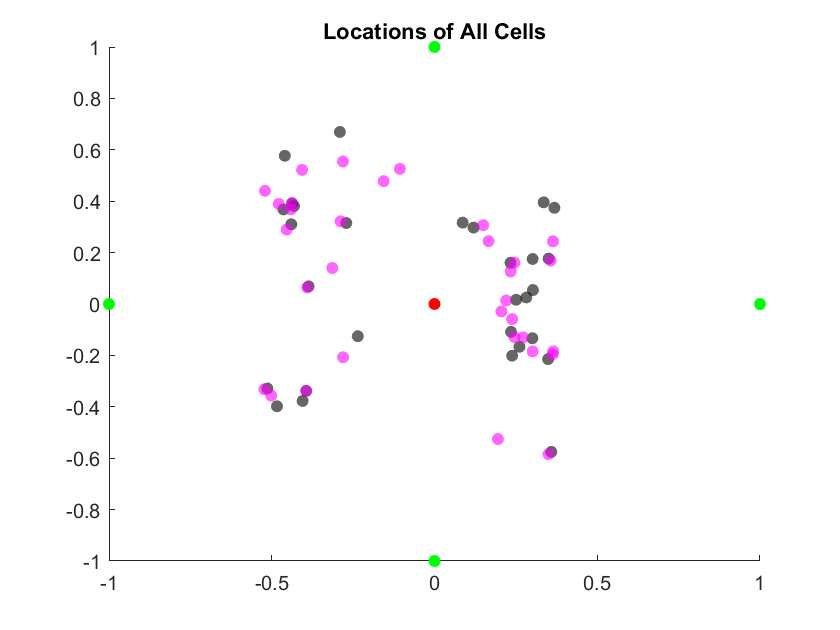

figure
title('Locations of All Cells')
hold on
scatter(upCoords(:, 1), upCoords(:, 2), 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoords(:, 1), downCoords(:, 2), 'filled', 'm', 'MarkerFaceAlpha', 0.6)
scatter([-1 0 1 0], [0, -1, 0 , 1], 'g', 'filled')
scatter([0], [0], 'r', 'filled')

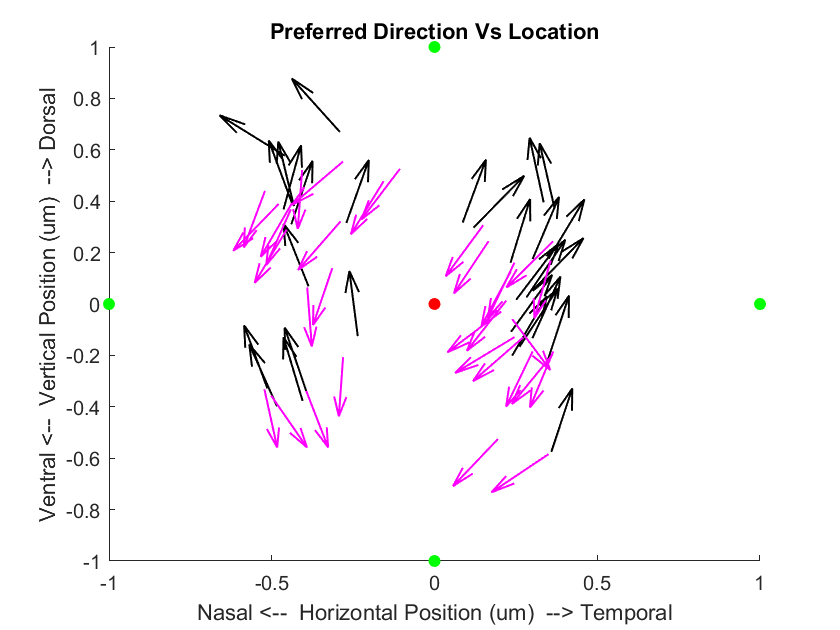

thetaDown = deg2rad(downPDs);
thetaUp = deg2rad(upPDs);
arrowLength = 0.1;

figure
title('Preferred Direction Vs Location')
hold on
quiver(upCoords(:, 1)', upCoords(:, 2)', arrowLength*cos(thetaUp), arrowLength*sin(thetaUp), '-k', 'LineWidth', 1)
quiver(downCoords(:, 1)', downCoords(:, 2)', arrowLength*cos(thetaDown), arrowLength*sin(thetaDown), '-m', 'LineWidth', 1)
xlabel('Nasal <--  Horizontal Position (um)  --> Temporal')
ylabel('Ventral <--  Vertical Position (um)  --> Dorsal')
scatter([-1 0 1 0], [0, -1, 0 , 1], 'g', 'filled')
scatter([0], [0], 'r', 'filled')

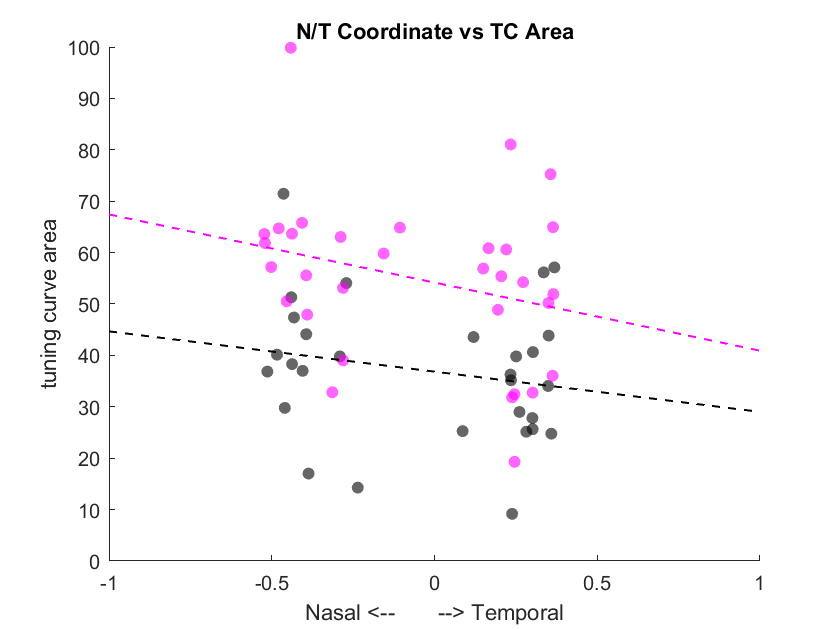


mdlUpAreas = fitlm(upCoords(:, 1), upTCAreas);
mdlDownAreas = fitlm(downCoords(:, 1), downTCAreas);
fitQueries = [-1:0.1:1];

upMdlPredictions = feval(mdlUpAreas, fitQueries);
downMdlPredictions = feval(mdlDownAreas, fitQueries);

figure
title('N/T Coordinate vs TC Area')
hold on
scatter(upCoords(:, 1), upTCAreas, 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoords(:, 1), downTCAreas, 'filled', 'm', 'MarkerFaceAlpha', 0.6)
xlabel('Nasal <--       --> Temporal')
ylabel('tuning curve area')
plot(fitQueries, upMdlPredictions, '--k', 'LineWidth', 1)
plot(fitQueries, downMdlPredictions, '--m', 'LineWidth', 1)

[r_up, p_up] = corr(upCoords(:, 1), upTCAreas', 'type', 'Spearman')

r_up = -0.1611

p_up = 0.4038

[r_down, p_down] = corr(downCoords(:, 1), downTCAreas', 'type', 'Spearman')

r_down = -0.3138

p_down = 0.0807

[r, p] =  corr([upCoords(:, 1); downCoords(:, 1)], [upTCAreas, downTCAreas]', 'type', 'Spearman')

r = -0.2505

p = 0.0516

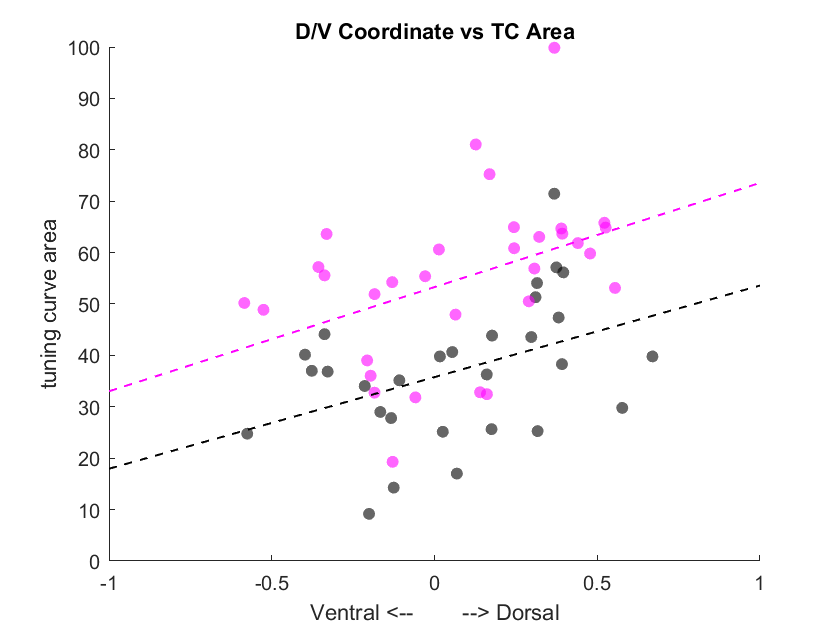

mdlUpAreas = fitlm(upCoords(:, 2), upTCAreas);
mdlDownAreas = fitlm(downCoords(:, 2), downTCAreas);
fitQueries = [-1:0.1:1];

upMdlPredictions = feval(mdlUpAreas, fitQueries);
downMdlPredictions = feval(mdlDownAreas, fitQueries);

figure
title('D/V Coordinate vs TC Area')
hold on
scatter(upCoords(:, 2), upTCAreas, 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoords(:, 2), downTCAreas, 'filled', 'm', 'MarkerFaceAlpha', 0.6)
xlabel('Ventral <--        --> Dorsal')
ylabel('tuning curve area')
plot(fitQueries, upMdlPredictions, '--k', 'LineWidth', 1)
plot(fitQueries, downMdlPredictions, '--m', 'LineWidth', 1)


[r_up, p_up] = corr(upCoords(:, 2), upTCAreas', 'type', 'Spearman')

r_up = 0.4259

p_up = 0.0212

[r_down, p_down] = corr(downCoords(:, 2), downTCAreas', 'type', 'Spearman')

r_down = 0.5059

p_down = 0.0035

[r, p] =  corr([upCoords(:, 2);downCoords(:, 2)], [upTCAreas, downTCAreas]', 'type', 'Spearman')

r = 0.3811

p = 0.0024

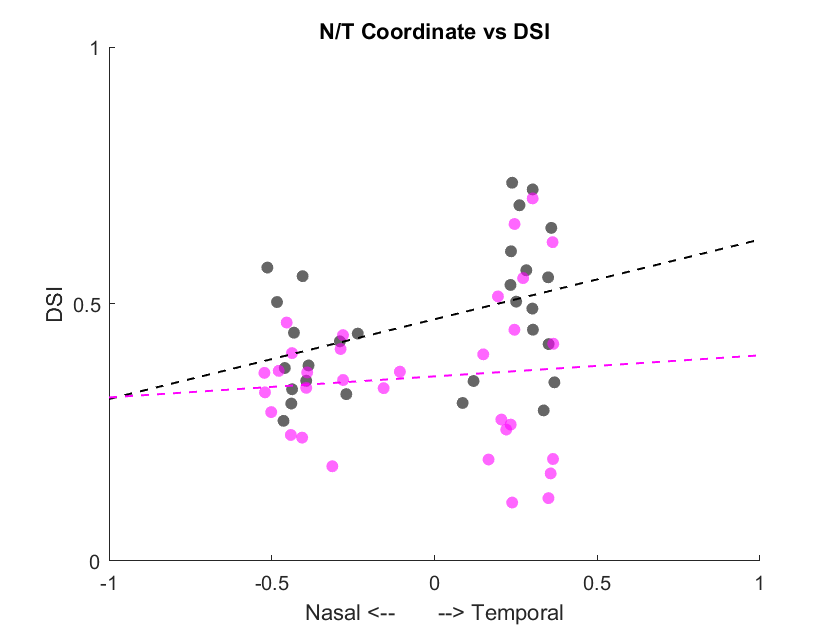

mdlUpAreas = fitlm(upCoords(:, 1), upDSIs);
mdlDownAreas = fitlm(downCoords(:, 1), downDSIs);
fitQueries = [-1:0.1:1];

upMdlPredictions = feval(mdlUpAreas, fitQueries);
downMdlPredictions = feval(mdlDownAreas, fitQueries);

figure
title('N/T Coordinate vs DSI')
hold on
scatter(upCoords(:, 1), upDSIs, 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoords(:, 1), downDSIs, 'filled', 'm', 'MarkerFaceAlpha', 0.6)
xlabel('Nasal <--       --> Temporal')
ylabel('DSI')
plot(fitQueries, upMdlPredictions, '--k', 'LineWidth', 1)
plot(fitQueries, downMdlPredictions, '--m', 'LineWidth', 1)
ylim([0 1])
yticks([0 0.5 1])

[r_up, p_up] = corr(upCoords(:, 1), upDSIs', 'type', 'Spearman')

r_up = 0.2788

p_up = 0.1428

[r_down, p_down] = corr(downCoords(:, 1), downDSIs', 'type', 'Spearman')

r_down = 0.0671

p_down = 0.7144

[r, p] =  corr([upCoords(:, 1);downCoords(:, 1)], [upDSIs, downDSIs]', 'type', 'Spearman')

r = 0.2148

p = 0.0965

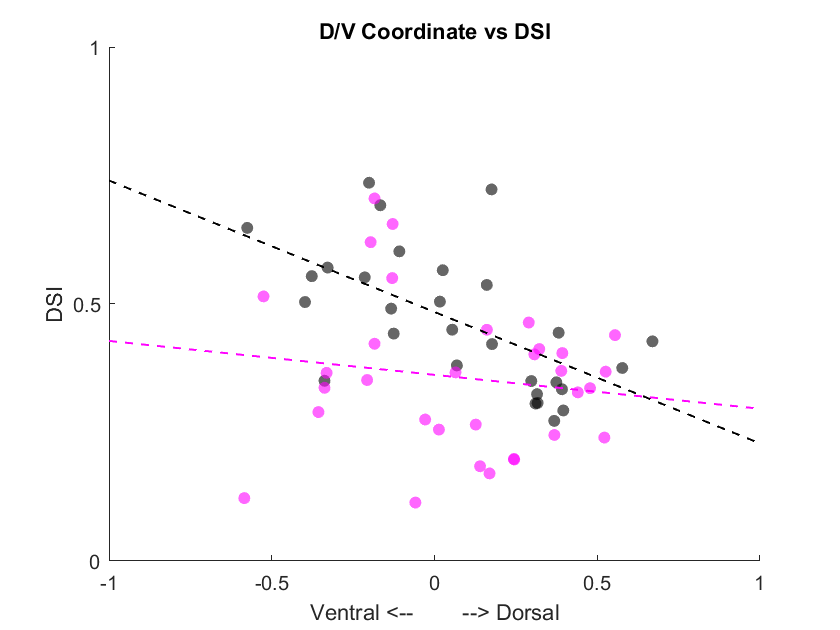

mdlUpAreas = fitlm(upCoords(:, 2), upDSIs);
mdlDownAreas = fitlm(downCoords(:, 2), downDSIs);
fitQueries = [-1:0.1:1];

upMdlPredictions = feval(mdlUpAreas, fitQueries);
downMdlPredictions = feval(mdlDownAreas, fitQueries);

figure
title('D/V Coordinate vs DSI')
hold on
scatter(upCoords(:, 2), upDSIs, 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoords(:, 2), downDSIs, 'filled', 'm', 'MarkerFaceAlpha', 0.6)
xlabel('Ventral <--        --> Dorsal')
ylabel('DSI')
plot(fitQueries, upMdlPredictions, '--k', 'LineWidth', 1)
plot(fitQueries, downMdlPredictions, '--m', 'LineWidth', 1)
ylim([0 1])
yticks([0 0.5 1])


[r_up, p_up] = corr(upCoords(:, 2), upDSIs', 'type', 'Spearman')

r_up = -0.6709

p_up = 1.0110e-04

[r_down, p_down] = corr(downCoords(:, 2), downDSIs', 'type', 'Spearman')

r_down = -0.0817

p_down = 0.6554

[r, p] =  corr([upCoords(:, 2);downCoords(:, 2)], [upDSIs, downDSIs]', 'type', 'Spearman')

r = -0.3454

p = 0.0064

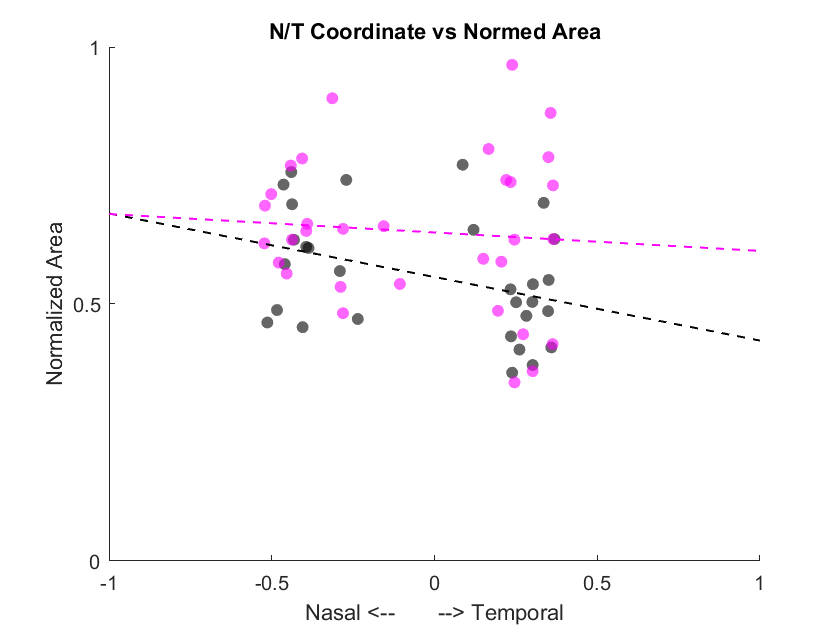

mdlUpAreas = fitlm(upCoords(:, 1), upNormedAreas);
mdlDownAreas = fitlm(downCoords(:, 1), downNormedAreas);
fitQueries = [-1:0.1:1];

upMdlPredictions = feval(mdlUpAreas, fitQueries);
downMdlPredictions = feval(mdlDownAreas, fitQueries);

figure
title('N/T Coordinate vs Normed Area')
hold on
scatter(upCoords(:, 1), upNormedAreas, 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoords(:, 1), downNormedAreas, 'filled', 'm', 'MarkerFaceAlpha', 0.6)
xlabel('Nasal <--       --> Temporal')
ylabel('Normalized Area')
plot(fitQueries, upMdlPredictions, '--k', 'LineWidth', 1)
plot(fitQueries, downMdlPredictions, '--m', 'LineWidth', 1)
ylim([0 1])
yticks([0 0.5 1])


[r_up, p_up] = corr(upCoords(:, 1), upNormedAreas', 'type', 'Spearman')

r_up = -0.2798

p_up = 0.1413

[r_down, p_down] = corr(downCoords(:, 1), downNormedAreas', 'type', 'Spearman')

r_down = -0.0612

p_down = 0.7385

[r, p] =  corr([upCoords(:, 1);downCoords(:, 1)], [upNormedAreas, downNormedAreas]', 'type', 'Spearman')

r = -0.2162

p = 0.0943

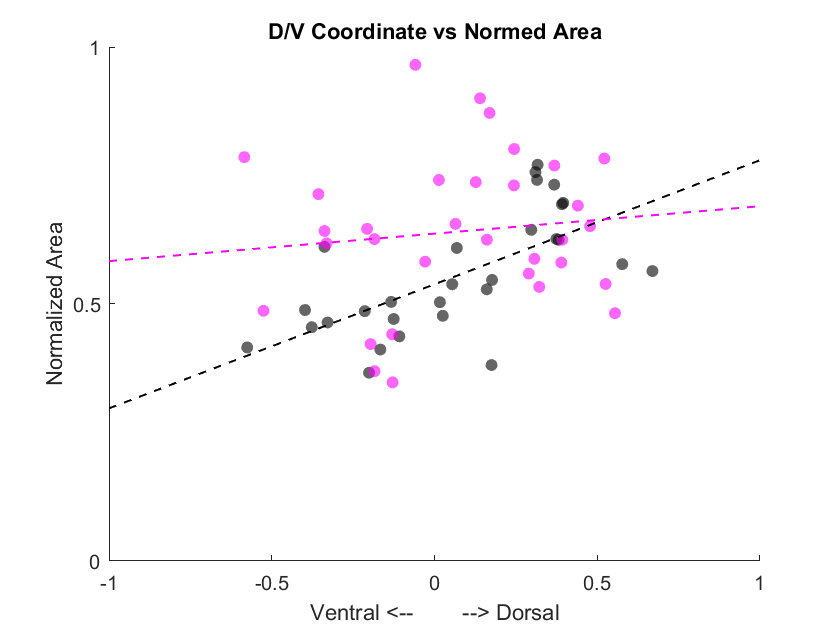

mdlUpAreas = fitlm(upCoords(:, 2), upNormedAreas);
mdlDownAreas = fitlm(downCoords(:, 2), downNormedAreas);
fitQueries = [-1:0.1:1];

upMdlPredictions = feval(mdlUpAreas, fitQueries);
downMdlPredictions = feval(mdlDownAreas, fitQueries);

figure
title('D/V Coordinate vs Normed Area')
hold on
scatter(upCoords(:, 2), upNormedAreas, 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoords(:, 2), downNormedAreas, 'filled', 'm', 'MarkerFaceAlpha', 0.6)
xlabel('Ventral <--        --> Dorsal')
ylabel('Normalized Area')
plot(fitQueries, upMdlPredictions, '--k', 'LineWidth', 1)
plot(fitQueries, downMdlPredictions, '--m', 'LineWidth', 1)
ylim([0 1])
yticks([0 0.5 1])


[r_up, p_up] = corr(upCoords(:, 2), upNormedAreas', 'type', 'Spearman')

r_up = 0.7034

p_up = 3.3884e-05

[r_down, p_down] = corr(downCoords(:, 2), downNormedAreas', 'type', 'Spearman')

r_down = 0.0554

p_down = 0.7629

[r, p] =  corr([upCoords(:, 2);downCoords(:, 2)], [upNormedAreas, downNormedAreas]', 'type', 'Spearman')

r = 0.3503

p = 0.0056